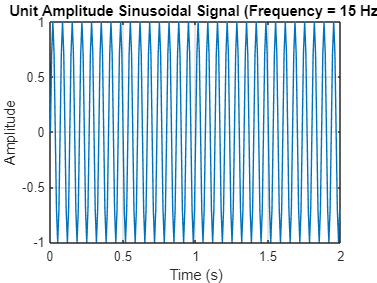

%Q1)
a = 1;            
duration = 2;        
sampling_rate = 120;  
Ts = 1 / sampling_rate;

% Calculate the total number of samples
N = duration * sampling_rate;
t = (0:N-1) * Ts;
f = 15 * a;
signal = sin(2 * pi * f * t);

figure;
plot(t, signal);
title(['Unit Amplitude Sinusoidal Signal (Frequency = ' num2str(f) ' Hz)']);
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

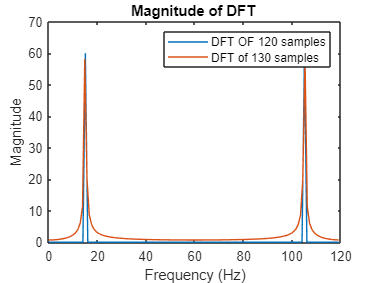


%Q1A,B,C)
a = 1;            
duration = 2;         
sampling_rate = 120; 
f = 15 * a; 
N = 120;

t = (0:N-1) / sampling_rate;
signal = sin(2 * pi * f* t);
fft_result = fft(signal(1:120));  
frequencies = (0:119) * (sampling_rate / 120);
magnitude3 = abs(fft_result);
figure;
A=plot(frequencies, magnitude3);
title(' DFT of First 120 Samples');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
hold on;

N2=130;
t2 = (0:N2-1) / sampling_rate;
signal = sin(2 * pi * f* t2);
fft_result2 = fft(signal(1:130));  
frequencies2 = (0:129) * (sampling_rate / 130);
magnitude2 = abs(fft_result2);

B=plot(frequencies2, magnitude2);
title('Magnitude of DFT ');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
legend([A,B],'DFT OF 120 samples','DFT of 130 samples');
hold off;

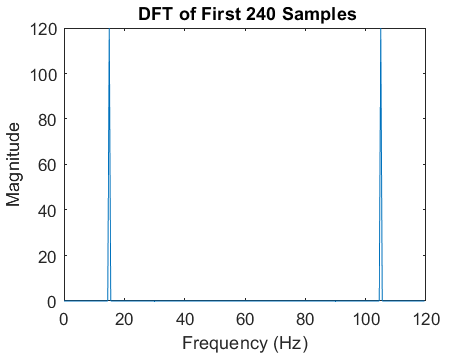



N1=240;
t9 = (0:N1-1) / sampling_rate;
signal = sin(2 * pi * f* t9);
fft_result3 = fft(signal(1:240));  
frequencies3 = (0:239) * (sampling_rate / 240);
magnitude3 = abs(fft_result3);
figure;
A=plot(frequencies3, magnitude3);
title(' DFT of First 240 Samples');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

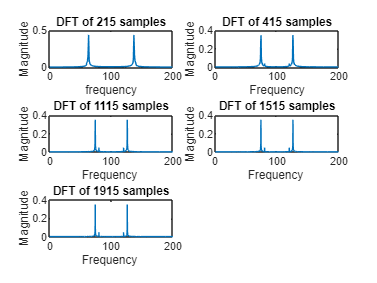

%q2)

%215 samples
t1= 0:1/200:(214/200);
% 200 since given in question

a = 1; A = 120; B = 126;
N1 = 215;
x = 0.1*sin(A*pi*t1) + cos(B*pi*t1) ;

dft1 = fft(x);
mag1 = abs(dft1);

freq1 = (0:N1-1) * (200 / N1);
plot(freq1 , mag1/N1)
title('DFT of 215 samples')
xlabel('frequency')
ylabel('Magnitude')
subplot(3,2,2)



%415 samples
t3= 0:1/200:(414/200);
% 200 since given in question

a= 1; A = 120; B = 126;
N3 = 415;
xa = 0.1*sin(2*A*pi*t3) + cos(2*B*pi*t3) ;

dft3 = fft(xa);
mag3 = abs(dft3);

freq3 = (0:N3-1) * (200 / N3);
plot(freq3 , mag3/N3)
title('DFT of 415 samples')
xlabel('Frequency')
ylabel('Magnitude')
subplot(3,2,3)




%1115 samples

t4= 0:1/200:(1114/200);
% 200 since given in question

a = 1; A = 120; B = 126;
N4= 1115;
xb = 0.1*sin(2*A*pi*t4) + cos(2*B*pi*t4) ;

dft4 = fft(xb);
mag4 = abs(dft4);

freq4 = (0:N4-1) * (200 / N4);
plot(freq4 , mag4/N4)

title('DFT of 1115 samples')
xlabel('Frequency ')
ylabel('Magnitude')
subplot(3,2,4)






%1515 samples
t5= 0:1/200:(1514/200);
% 200 since given in question
a = 1; A = 120; B = 126;
N5 = 1515;
xc = 0.1*sin(2*A*pi*t5) + cos(2*B*pi*t5) ;

dft5 = fft(xc);
mag5 = abs(dft5);

freq5 = (0:N5-1) * (200 / N5);
plot(freq5 , mag5/N5)
title('DFT of 1515 samples')
xlabel('Frequency ')
ylabel('Magnitude')
subplot(3,2,5)



%1915 samples
t6= 0:1/200:(1914/200);
% 200 since given in question
a = 1; A = 120; B = 126;
N6 = 1915;
xd = 0.1*sin(2*A*pi*t6) + cos(2*B*pi*t6) ;

dft6= fft(xd);
mag6 = abs(dft6);

freq6= (0:N6-1) * (200 / N6);
plot(freq6 , mag6/N6)
title('DFT of 1915 samples')
xlabel('Frequency ')
ylabel('Magnitude')
subplot(3,2,1)

%Q3)

%215 samples
t1= 0:1/200:(214/200);


a = 1; A = 120; B = 126;
N1 = 215;
x=  0.1*sin(2*A*pi*t1) + cos(2*B*pi*t1) ;

dft1 = fft(x);
mag1 = abs(dft1);

freq1 = (0:N1-1) * (200 / N1);
plot(freq1 , mag1/N1)
title('x(t) = 0.1sin(120*πt) + cos(126*πt)*(transpose(hann(215))')
xlabel('frequency')
ylabel('Magnitude')




%415 samples
t3= 0:1/200:(414/200);
% 200 since given in question

a= 1; A = 120; B = 126;
N3 = 415;
xa =  0.1*sin(2*A*pi*t3) + cos(2*B*pi*t3) ; 

dft3 = fft(xa);
mag3 = abs(dft3);

freq3 = (0:N3-1) * (200 / N3);
plot(freq3 , mag3/N3)
title('x(t) = 0.1sin(120*πt) + cos(126*πt)*(transpose(hann(415))')
xlabel('Frequency')
ylabel('Magnitude')





%1115 samples

t4= 0:1/200:(1114/200);
% 200 since given in question

a = 1; A = 120; B = 126;
N4= 1115;
xb = 0.1*sin(2*A*pi*t4) + cos(2*B*pi*t4) ;

dft4 = fft(xb);
mag4 = abs(dft4);

freq4 = (0:N4-1) * (200 / N4);
plot(freq4 , mag4/N4)

title('x(t) = 0.1sin(120*πt) + cos(126*πt)*(transpose(hann(1115))')
xlabel('Frequency ')
ylabel('Magnitude')







%1515 samples
t5= 0:1/200:(1514/200);
% 200 since given in question
a = 1; A = 120; B = 126;
N5 = 1515;
xc =  0.1*sin(2*A*pi*t5) + cos(2*B*pi*t5)

xc =     1.0000   -0.7433    0.0323    0.6754   -0.9333    0.5878    0.1286   -0.7492    0.8735   -0.4230   -0.3090    0.8460   -0.8347    0.2730    0.4846   -0.9511    0.8175   -0.1536   -0.6309    1.0411   -0.8090    0.0666    0.7325   -1.0931    0.7877    0.0000   -0.7877    1.0931   -0.7325   -0.0666    0.8090   -1.0411    0.6309    0.1536   -0.8175    0.9511   -0.4846   -0.2730    0.8347   -0.8460    0.3090    0.4230   -0.8735    0.7492   -0.1286   -0.5878    0.9333   -0.6754   -0.0323    0.7433


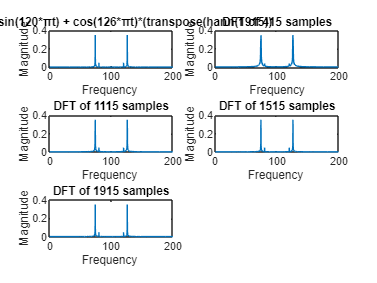


dft5 = fft(xc);
mag5 = abs(dft5);

freq5 = (0:N5-1) * (200 / N5);
plot(freq5 , mag5/N5)
title('x(t) = 0.1sin(120*πt) + cos(126*πt)*(transpose(hann(1515))')
xlabel('Frequency ')
ylabel('Magnitude')




%1915 samples
t6= 0:1/200:(1914/200);
% 200 since given in question
a = 1; A = 120; B = 126;
N6 = 1915;
xd= 0.1*sin(2*A*pi*t6) + cos(2*B*pi*t6);

dft6= fft(xd);
mag6 = abs(dft6);

freq6= (0:N6-1) * (200 / N6);
plot(freq6 , mag6/N6)
title('x(t) = 0.1sin(120*πt) + cos(126*πt)*(transpose(hann(1915))')
xlabel('Frequency ')
ylabel('Magnitude')

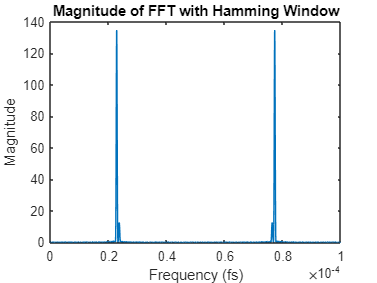


%q4
data = load('Exp4Data1.txt');
fs = 1; 
T=1/fs;
t=0:T:duration-T;
N = length(data);

%q4(a)
window = hamming(N);
data_window = data .* window';

n= 10000;
fft_new = fft(data_window, n);
freq = (0:n-1) * (fs / n);
freq_normalized = freq / n;
figure;
plot(freq_normalized, abs(fft_new));
title('Magnitude of FFT with Hamming Window');
xlabel('Frequency (fs)');
ylabel('Magnitude');


[~, max_indices] = maxk(abs(fft_new), 2);
frequencies = freq_normalized(max_indices);
disp(['Estimated Frequencies using Hamming Window: ', num2str(sort(frequencies))]);

Estimated Frequencies using Hamming Window: 2.281e-05   7.719e-05


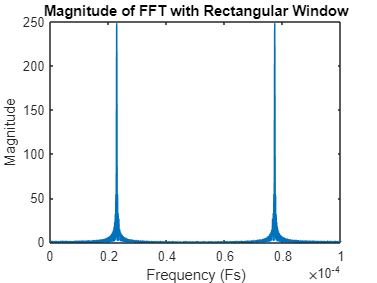


%q4(b)
window_rect = rectwin(N);
data_window_rect = data .* window_rect';
fft_rect = fft(data_window_rect, n);
figure;
plot(freq_normalized, abs(fft_rect));
title('Magnitude of FFT with Rectangular Window');
xlabel('Frequency (Fs)');
ylabel('Magnitude');


[~, max_indices] = maxk(abs(fft_rect), 2);
frequencies1 = freq_normalized(max_indices);
disp(['Estimated Frequencies using Rectangular Window: ', num2str(sort(frequencies1))]);

Estimated Frequencies using Rectangular Window: 2.281e-05   7.719e-05
